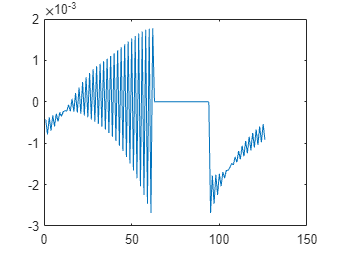

% Solving the equations %

plot(P_mat_prsd)

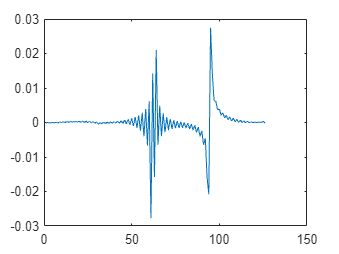

Traction_f = mldivide(I_mat_prsd,P_mat_prsd);
plot(Traction_f)

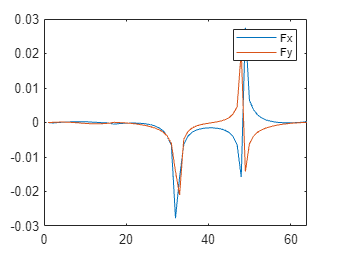

Fx = Traction_f(1:2:end);
Fy = Traction_f(2:2:end);
Fxm = zeros(N_o_el,1);
Fym = zeros(N_o_el,1);
for n = 1:N_o_el-1
    Fxm(n+1) = Fx(n);
end
for n = 1:N_o_el-1
    Fym(n+1) = Fy(n);
end


plot(Fxm)
hold on
plot(Fym)
legend("Fx","Fy")
hold off

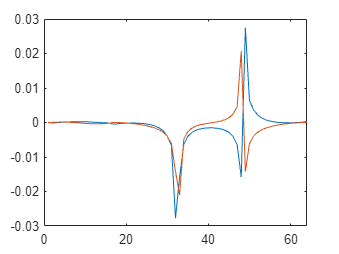


F = zeros(N_o_el,2);
for n = 1:N_o_el
    F(n,1) = Fxm(n);
    F(n,2) = Fym(n);
end
